rand_init = randn(9, 1)*0.005*0;
rand_init = rand_init - mean(rand_init);
rand_init = rand_init + 1;
load('FFnet.mat', 'FFnet')

# M3C Simulation

## Parameters

Simulation and control steps

%% Simulation
Tf = 1;                      % Time length
Ts = 2e-5;	                 % Sample time
Ns = round(Tf/Ts + 1);       % Number of steps
Tsim = linspace(0, Tf, Ns);
%% Total energy balance
Ti = 1e-4;                   % Sample time
Ni = round(Tf/Ti + 1);       % Number of steps
Tcur = linspace(0, Tf, Ni);
%% ICB + LFOM
Tl = 1e-4;                   % Sample time
Nl = round(Tf/Tl + 1);       % Number of steps
lmax = 10;                   % BCD solver max iterations
Ten = linspace(0, Tf, Nl);
% Prediction horizon
Np = 1;
tp = linspace(0, Np*Tl, Np);

Converter model

% M3C incidence matrix
A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m = size(A, 2);
N = null(A, 'rational');
pinvN = pinv(N);
n = size(N, 2);          % Number of circulating currents
C = 20e-3;			     % Average cluster capacitance
L = 200e-4;              % Branch inductance
R = 0.001;			     % Branch resistance

Current discrete model

% Fundamental step size
Ad_s = expm(-Ts*R/L*eye(m));
Bd_s = (-R/L*eye(m))\(Ad_s-eye(m))*(-eye(m)/L);

% Energy and current control step size
Ad_l = expm(-Tl*R/L*eye(m));
Bd_l = (-R/L*eye(m))\(Ad_l-eye(m))*(-eye(m)/L);

Let's assume we know exactly the future grid voltage

% Input
Ax = 7000;
fx0 = 50;
wx0 = 2*pi*fx0;
% Output
Ay = 5000;
fy0 = 50;
wy0 = 2*pi*fy0;

Maneuver (just output frequency variation for the beta version. the control must be validated with variation of references and disturbances)

Tini = 1;                   % Initial time
Tfin = 1.5;                   % Final time
fyf = 50;                     % Final frequency
wyf = fyf*2*pi;               % Final speed
acel = (wyf-wy0)/(Tfin-Tini); % Acceleration

isManeuver = (Tini < Tsim) & (Tsim < Tfin);
accelVector = acel * isManeuver;
wy = wy0 + Ts*cumsum(accelVector);
wx = wx0 *ones(1, Ns);

% Timeseries
gx = Ts*cumsum(wx);
gy = Ts*cumsum(wy);
vxa = Ax*cos(gx);
vxb = Ax*cos(gx-2*pi/3);
vxc = Ax*cos(gx+2*pi/3);
vyr = Ay*cos(gy);
vys = Ay*cos(gy-2*pi/3);
vyt = Ay*cos(gy+2*pi/3);

vxy = [vxa; vxb; vxc; vyr; vys; vyt];
vB = A'*vxy;

## Supervised leaning control of M3C

Train NN to imitate ICB and LFOM control (generate circulating currents and common model voltage references).

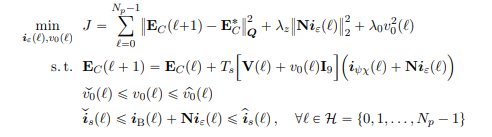

## Simulation

Diagonal matrix

D = @(vector) diag(vector);

Reference frame transformations

Tabc_ab = (2/3)*[1, -1/2, -1/2; 0, sqrt(3)/2, -sqrt(3)/2];
Tab_abc = [1, 0; -1/2, sqrt(3)/2; -1/2, -sqrt(3)/2];

Tabc_dq_function = @(g) (2/3)*[cos(g), cos(g-2*pi/3), cos(g+2*pi/3); -sin(g), -sin(g-2*pi/3), -sin(g+2*pi/3)];

Limit values

Vxy_max = Ax+Ay;     % Branch voltage
Von_max = Vxy_max/2; % Common mode voltage
Is_max = 250;        % Cluster current
Ix_max = 200;        % Input current

Constant references

%% Cluster capacitor voltage reference
vc_ref = 1.5*Vxy_max;
%% Cluster capacitor energy reference
Ec_ref = vc_ref^2*C/(4*2);

Control parameters and initialization

- TEB

% Parameters
Kp_teb = 6.48156886919677*3;
Ki_teb = 397.264633627808/20;
n_teb = 1-Ti*0.5*Ki_teb/Kp_teb;
% Initialization
[a_teb, u_teb] = deal(0);
[Ixd_ref, Ixq_ref] = deal(zeros(1, Ns));
[ixa_ref, ixb_ref, ixc_ref, iyr_ref, iys_ref, iyt_ref] = deal(zeros(1, Ns));
ixy_ref = zeros(6, Ns);
iB_ref = zeros(m, Ns);

%% dq output current reference (this must come from the converter's application)
% Iy_dref = 10*ones(1, Ns); % Iyd_ref(t) = 200; -> Maneuver
% Iy_qref = 60*ones(1, Ns);
Iyd_ref = 150*ones(1, Ns);
Iyq_ref = 0*ones(1, Ns);

- ICB + LFOM

% Parameters
lambdai = 2*Np;
lambdav = 0.1*Np;
% Initialization
iAi = false(size([ones(m*Np, 1); -ones(m*Np, 1)]));
iAv = false(size([ones(Np, 1); -ones(Np, 1)]));
Tex = zeros(1, Ns);                                % Controller execution time
t_en = 1;                                          % Index time step
ie_ref = deal(zeros(n, Ns));
[is_ref, iz_ref] = deal(zeros(m, Ns));
von = zeros(1, Ns);

- Cluster current control

% Parameters
lambda = 0.00005;
% Initialization
iA = false(size([ones(m*Np, 1); -ones(m*Np, 1)]));
vs = deal(zeros(m, Ns));

Initialization

ixy = deal(zeros(6, Ns));
iB = deal(zeros(m, Ns));
[is, Ec] = deal(zeros(m, Ns+1));
vc0 = vc_ref*ones(m, 1) .* rand_init; % Cluster capacitor voltage
Ec0 = (C/2/4)*vc0.^2; % Cluster energy
is(:, 1) = zeros(m, 1);
Ec(:, 1:2) = [Ec0 Ec0];

Run

for t = 1:length(Tsim)
    
    % External and basic currents
    ixy(:, t) = A*is(:, t);
    iB(:, t) = pinvA*ixy(:, t);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% TEB control
    if any(Tcur==Tsim(t))

        % TEB PI
        e_teb = (vc_ref-sqrt(4*2*abs(mean(Ec(:, t)))*sign(mean(Ec(:, t)))/C));
        a_teb = (n_teb-1)*u_teb/Kp_teb+a_teb*n_teb;
        u_teb = (e_teb-a_teb)*Kp_teb;
        u_teb = clip(u_teb, -Ix_max, Ix_max); % Saturation between Ix_max*[-1, 1]

        Ixd_ref(t) = u_teb;
        ixa_ref(t) = Ixd_ref(t)*cos(gx(t))        - Ixq_ref(t)*sin(gx(t));
        ixb_ref(t) = Ixd_ref(t)*cos(gx(t)-2*pi/3) - Ixq_ref(t)*sin(gx(t)-2*pi/3);
        ixc_ref(t) = Ixd_ref(t)*cos(gx(t)+2*pi/3) - Ixq_ref(t)*sin(gx(t)+2*pi/3);
        
        iyr_ref(t) = Iyd_ref(t)*cos(gy(t))        - Iyq_ref(t)*sin(gy(t));
        iys_ref(t) = Iyd_ref(t)*cos(gy(t)-2*pi/3) - Iyq_ref(t)*sin(gy(t)-2*pi/3);
        iyt_ref(t) = Iyd_ref(t)*cos(gy(t)+2*pi/3) - Iyq_ref(t)*sin(gy(t)+2*pi/3);
        
        ixy_ref(:, t) = [ixa_ref(t); ixb_ref(t); ixc_ref(t); iyr_ref(t); iys_ref(t); iyt_ref(t)];
        iB_ref(:, t) = pinvA*ixy_ref(:, t);
    else % Hold control signals until next TEB control interrupt
        %%% TEB
        Ixd_ref(t) = Ixd_ref(t-1);
        Ixq_ref(t) = Ixq_ref(t-1);
        Ixd_ref(t) = Ixd_ref(t-1);
        Iyq_ref(t) = Iyq_ref(t-1);
        iyr_ref(t) = iyr_ref(t-1);
        iys_ref(t) = iys_ref(t-1);
        iyt_ref(t) = iyt_ref(t-1);
        ixa_ref(t) = ixa_ref(t-1);
        ixb_ref(t) = ixb_ref(t-1);
        ixc_ref(t) = ixc_ref(t-1); 
        iB_ref(:, t) = iB_ref(:, t-1);
        ixy_ref(:, t) = ixy_ref(:, t-1);
    end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ICB + LFOM control
    if any(Ten == Tsim(t))
        tic        
        %%% Input data
        x = [Ec(:, t); vB(:, t); iB(:, t)] ./ Xmax;

        %%% RegLin
        % x_bias = [1; x];
        % PRED = weights * x_bias .* Ymax;

        %%% FFNN
        x = dlarray(x, 'CB');
        PRED = extractdata(FFnet.predict(x) .* Ymax);

        %%% RNN
        % x = dlarray(x, 'CTB');
        % xseq = xseq_fifo_update(xseq, x);
        % PRED = extractdata(Rnet.predict(xseq) .* Ymax);

        %%% PINN
        % x = dlarray(x, 'CB');
        % PRED = extractdata(PInet.predict(x) .* Ymax);

        Tex(t) = toc;

        ie_ref(:, t) = PRED(1:4);
        iz_ref(:, t) = N*ie_ref(:, t);
        von(t) = PRED(5);

        is_ref(:, t) = iB_ref(:, t)+iz_ref(:, t);
        
        t_en = t_en + 1;
    else % Hold control signals until ICB + LFOM control interrupt
        %%% ICB + LFOM
        Tex(t) = Tex(t-1);
        ie_ref(:, t) = ie_ref(:, t-1);
        iz_ref(:, t) = iz_ref(:, t-1);
        von(t) = von(t-1);
        is_ref(:, t) = is_ref(:, t-1);
    end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CC control
    if any(Ten==Tsim(t))
        Hi =  2*Bd_l'*Bd_l;
        fi = 2*Bd_l'*(Ad_l*is(:, t)-is_ref(:, t));
        Hv = eye(m);
        fv = zeros(m, 1);
        H = Hi + lambda*Hv;
        f = fi + lambda*fv;
        H = (H+H')/2;
        options = mpcActiveSetOptions;
        options.MaxIterations = 100;
        options.ConstraintTolerance = 1.0e-4;
        p = -(vB(:, t) + von(t));
        ub = vc_ref*ones(m, 1) - p;
        lb = -ub;
        [Z, exitflag, iA, mu] = mpcActiveSetSolver(H, f, [eye(m); -eye(m)], [ub; -lb], zeros(0, m), zeros(0, 1), iA, options);
        vs(:, t)=Z-p;
    else % Hold control signals until next CC control interrupt
        vs(:, t) = vs(:, t-1);
    end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Update state variables
    is(:, t+1) = is(:, t)*(1-Ts*R/L) + (Ts/L)*(vB(:, t) + von(t) - vs(:, t));
    Ec(:, t+1) = Ec(:, t) + Ts*vs(:, t).*is(:, t);
end

Unrecognized function or variable 'Xmax'.

iz = is(:, 1:end-1) - iB;
ie = pinvN * iz;
vc = sqrt(2*4*abs(Ec).*sign(Ec)/C);
vcmean = mean(vc(:, 1:end-1));
Ec_mean = mean(Ec(:, 1:end-1));

# Results

Save

actual_run = struct();
actual_run.Ec = Ec;
actual_run.Ec_ref = mean(Ec);
actual_run.vxy = vxy;
actual_run.vB = vB;
actual_run.ixy = ixy;
actual_run.iB = iB;
actual_run.ixy_ref = ixy_ref;
actual_run.ixy_ref = ixy_ref;
actual_run.vs = vs;
actual_run.is = is;
actual_run.ie = ie;
actual_run.von = von;

## Control outputs

clc
close all

Linear independent circulating currents

figure
subplot(ceil(n/2), 2, 1)
plot(Tsim, ie_ref(1, :))
hold on
plot(Tsim, ie(1, :), '--', 'LineWidth', 2)
hold off
for idx = 2:n
    subplot(ceil(n/2), 2, idx)
    plot(Tsim, ie_ref(idx, :))
    hold on
    plot(Tsim, ie(idx, :), '--', 'LineWidth', 2)
    hold off
end
sgtitle('Linear Independent Circulating Currents (A)')

Common mode voltage

figure
plot(Tsim, von)
xlabel('Time (s)')
ylabel('Common mode voltage (V)')

Controller execution time

figure
plot(Tsim, Tex)
xlabel('Time (s)')
ylabel('ICB + LFOM ET (s)')
ylim([0 0.05])

## Other variables

External Currents

figure

subplot(2, 1, 1)
plot(Tsim, ixy_ref(1:3, :))
hold on
plot(Tsim, ixy(1:3, :), '--', 'LineWidth', 2)
hold off
ylabel('Input Currents (A)')

subplot(2, 1, 2)
plot(Tsim, ixy_ref(4:6, :))
hold on
plot(Tsim, ixy(4:6, :), '--', 'LineWidth', 2)
hold off
ylabel('Output Currents (A)')

xlabel('Time (s)')

Cluster Currents

figure
subplot(ceil(m/3), 3, 1)
plot(Tsim, is_ref(1, :))
hold on
plot(Tsim, is(1, 1:end-1), '--', 'LineWidth', 2)
hold off
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, is_ref(idx, :))
    hold on
    plot(Tsim, is(idx, 1:end-1), '--', 'LineWidth', 2)
    hold off
end
sgtitle('Cluster Currents (A)')

Circulating Currents

figure
subplot(ceil(m/3), 3, 1)
plot(Tsim, iz_ref(1, :))
hold on
plot(Tsim, iz(1, :), '--', 'LineWidth', 2)
hold off
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, iz_ref(idx, :))
    hold on
    plot(Tsim, iz(idx, :), '--', 'LineWidth', 2)
    hold off
end
sgtitle('Circulating Currents (A)')

Filter Voltages

figure
vF = von+vB-vs;
% vF = is(:, 1:end-1)*R+L*diff(is, 1, 2)/Ts;
subplot(ceil(m/3), 3, 1)
plot(Tsim, vF(1, :))
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, vF(idx, :))
end
sgtitle('Filter Voltages (V)')

Cluster and Branch Voltages

figure
subplot(ceil(m/3), 3, 1)
plot(Tsim, vs(1, :))
hold on
plot(Tsim, vB(1, :), '--', 'LineWidth', 2)
hold off
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, vs(idx, :))
    hold on
    plot(Tsim, vB(idx, :), '--', 'LineWidth', 2)
    hold off
end
sgtitle("Cluster and Branch Voltages (V)")

Mean Capacitor Voltage

figure
plot(Tsim, vcmean)
hold on
yline(vc_ref)
xlabel('Time (s)')
ylabel('Mean Capacitor Voltage (V)')

Capacitor Voltage Deviation, Capacitor Voltage Standard Deviation

figure
plot(Tsim, vc(:, 1:end-1)-vcmean)
ylabel('Capacitor Voltage Deviation (V)')

yyaxis right
vsd = 100*std((vc(:, 1:end-1)-vcmean)./vcmean, 0, 1);
plot(Tsim, vsd, 'LineStyle', '--', 'LineWidth', 2, 'Color', [0, 0, 0])
ax = gca;
ax.YColor = [0, 0, 0];
ylabel('Capacitor Voltage Standard Deviation (%)')

grid on
xlabel('Time (s)')

RMS Basic Current, Circulating Current

b = 500; % Window length
izrms = mean(sqrt(movmean(iz.^2, b, 2)), 1);
iBrms = mean(sqrt(movmean(iB.^2, b, 2)), 1);

figure

plot(Tsim, iBrms, 'Color', 'b')
hold on
plot(Tsim, izrms, 'Color', 'r')
hold off
ylabel('Average RMS Current (A)')

yyaxis right
plot(Tsim, izrms./iBrms, 'LineStyle', '--', 'Color', 'm')
ax = gca;
ax.YColor = 'm';
ylabel('iz/iB RMS ratio')

grid on
xlabel('Time (s)')
legend('Basic Current', 'Circulating Current', 'Z/B ratio')

Cluster Energy

figure
plot(Tsim, Ec(:, 1:end-1))
hold on
plot(Tsim, Ec_mean, 'LineWidth', 2)
hold off
yline(Ec_ref, '--')
grid on
xlabel('Time (s)')
ylabel('Cluster Energy')